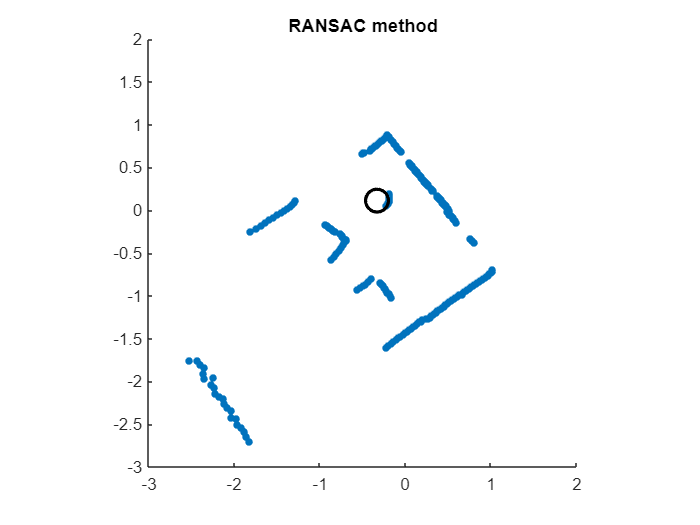

Output argument "circ_x" (and possibly others) not assigned a value in the execution with "ransac_circ" function.

load playpensample.mat
index=find(r~=0);
r_clean=r(index);
theta_clean=theta(index);
figure;
[x,y]=pol2cart(deg2rad(theta_clean),r_clean);

figure;
clf
hold on
scatter(x,y,20'.', "filled")

axis equal

k_rad = 0.1329;
[xc, yc] = ransac_circ(x, y, k_rad);

% t = linspace(0,2*pi,100);
% circ_x = k_rad * cos(t) + xc;
% circ_y = k_rad * sin(t) + yc;
% plot(circ_x, circ_y, "linewidth", 2)


Mdalineie is funnynr
